# Control integral,

Vamos a tomar el sistema de otros ejemplos, pero esta vez vamos a tomar directamente un sistema con una entrada y una salida,


$$$A_c =\pmatrix{1&2&0 \cr
-2&3&0\cr
1&0&-2}, \ B = \pmatrix{2\cr
1\cr
-1}$$



$$C_0 = \pmatrix{1& 2& 1}$$


Ac = [1 2 0; -2 3 0; 1 0 -2];
B = [2;1;-1];
Co = [1 2 1];
rank(ctrb(Ac,B)) %comprobamos que es controlable

ans = 3

Debemos construir una matriz ampliada para incluir el error entre la salida y el valor deseado en el sistema,

$A_{mp} =\pmatrix{A & 0 \cr C_2 & 0}$,$B_{mp} =\pmatrix{B \cr 0}$

Y comprobar que el par ampliado es controlable

Amp = [Ac zeros(3,1);Co 0]

Amp =      1     2     0     0
    -2     3     0     0
     1     0    -2     0
     1     2     1     0


Bmp = [B;0]

Bmp =      2
     1
    -1
     0


rank(ctrb(Amp,Bmp))

ans = 4

Por tanto la ampliada es controlable.

El sistema ampliado con el término de control integral quedaría,


$$\pmatrix{\dot{x} \cr \dot e_i} = \pmatrix{A -BK& -BK_I\cr C_2 & 0} \pmatrix{x \cr e}+ \pmatrix{0 \cr -I}y_d$$


 Podemos emplear directamente place para colocar los autovalores del sistema y el del error.

lambda = [-1 -2 -3 -4]; %el último 
% corresponde a la acción integral
K = place(Amp,Bmp,lambda)

K =    12.4615  -13.2308   -0.3077   -0.6154


calculamos ahora la matriz con las realimentaciones,

Ampr = [Ac-B*K(1:3) -B*K(4); Co 0]

Ampr =   -23.9231   28.4615    0.6154    1.2308
  -14.4615   16.2308    0.3077    0.6154
   13.4615  -13.2308   -2.3077   -0.6154
    1.0000    2.0000    1.0000         0


Ahora nuestra única entrada es un valor de consigna que la salida debe seguir. Elegimos por ejemplo yd = 15 y construimos una función adecuada para simular nuestro sistema (ver a final del archivo.

yd = 15;
sys = @(t,x)sistema_lineal_I(t,x,yd,Ampr);
tf = 10;
x0 = [1;-3;2;0]; %el cuarto valor corresponde al error

%opciones = odeset('maxstep',1e-5);
[t,x] = ode45(sys,[0,tf],x0);%,opciones);
figure(1)

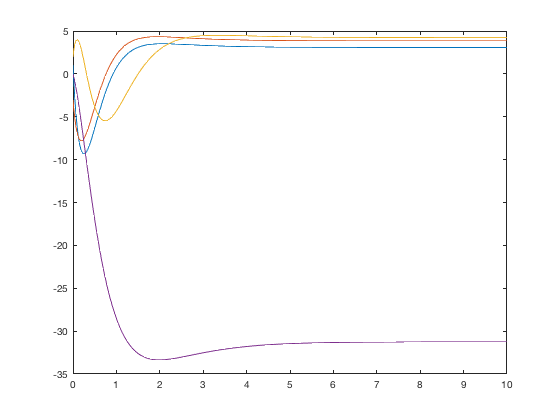

plot(t,x)

Si representamos la salida,

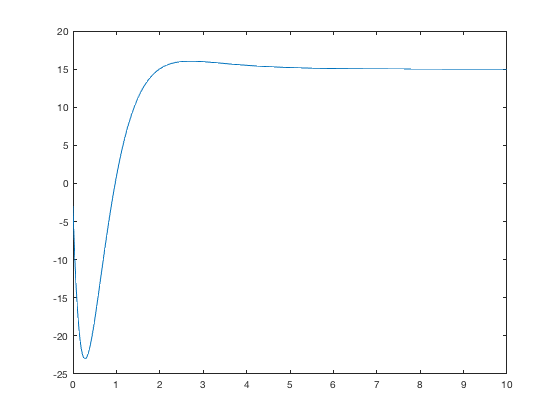

figure(2)
plot(t,Co*x(:,1:3)')

Supongamos ahora que no tenemos acceso a los estados.

En ese caso, podríamos emplear un observador siempre y cuando el sistema sea observable. Vamos a comprobarlo,

rank(obsv(Ac,Co))

ans = 3

Como el rango es tres, nuestro sistema es observable

Debemos ahora colocar los autovalores del observador de modo que sean algo más rápidos (parte real más a la izquierda) que los del controlador.

lambda = [-2, -3 -4];
Ko = place(Ac',Co',lambda)

Ko =    -0.1667    5.9167   -0.6667


L = Ko'

L =    -0.1667
    5.9167
   -0.6667


Ahora ya tenemos todos los ingredientes, Debemos construir una matriz ampliada que incluya tanto el observador como el error. Recordad que por el principio de separacion no hace falta volver a comprobar la controlabilidad de la nueva matriz ampliada:

$\pmatrix{\dot{x}\cr \dot{\hat{x}}\cr \dot{e}}A_{mpo} =\pmatrix{A & -BK &-BK_i\cr LC& A-BK-LC\ & -BK_i &\cr C_2 &0 &0}\pmatrix{x\cr \hat{x}\cr e}+ \pmatrix{0\cr 0\cr -yd} $,

Donde, lógicamente también pasamos en error integral al estimador.

Ampo = [Ac -B*K(1:3) -B*K(4)
        L*Co Ac-B*K(1:3)-L*Co -B*K(4)
        Co zeros(1,3) 0]

Ampo =     1.0000    2.0000         0  -24.9231   26.4615    0.6154    1.2308
   -2.0000    3.0000         0  -12.4615   13.2308    0.3077    0.6154
    1.0000         0   -2.0000   12.4615  -13.2308   -0.3077   -0.6154
   -0.1667   -0.3333   -0.1667  -23.7564   28.7949    0.7821    1.2308
    5.9167   11.8333    5.9167  -20.3782    4.3974   -5.6090    0.6154
   -0.6667   -1.3333   -0.6667   14.1282  -11.8974   -1.6410   -0.6154
    1.0000    2.0000    1.0000         0         0         0         0


Construimos ahora una función para poder integrarla con ode45 (ver el final)

yd = 15;

Creamos un vector de entradas que contenga, los estados, los estimadores y el error. 

x0 = [1;-3;2;2;1;-1;0]; 
sys = @(t,x)sistema_lineal_IO(t,x,yd,Ampo);
tf =15 %le damos un poquito mas de tiempo..

tf = 15

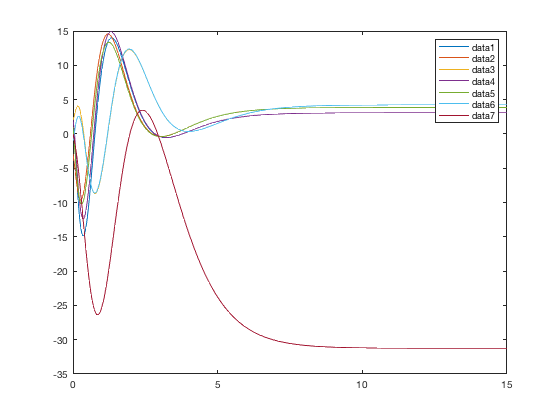

%opciones = odeset('maxstep',1e-5);
[t,x] = ode45(sys,[0,tf],x0);%,opciones);
figure(3)
plot(t,x)
legend

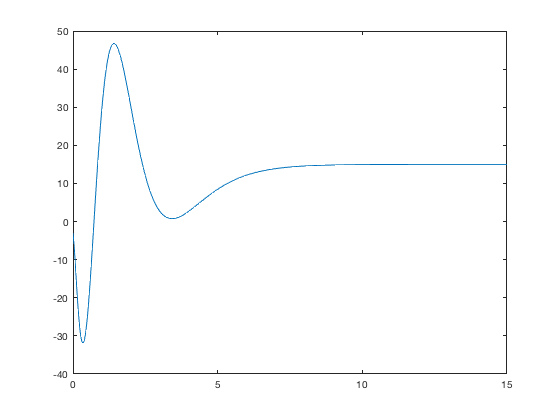

%pintamos las salidas
figure(4)
plot(t,Co*x(:,1:3)')

function xdot = sistema_lineal_I(t,x,yd,A)
%modificamos el sistema lineal para ponerlo en modo realimentación
%Debemos añadir la entrada al error, que corresponde a yd
xdot = A*x+[zeros(size(x,1)-length(yd),1);-yd];
end
function xdot = sistema_lineal_IO(t,x,yd,A)
%modificamos el sistema lineal para ponerlo en modo realimentación
%Debemos añadir la entrada al error, que corresponde a yd
xdot = A*x+[zeros(size(x,1)-length(yd),1);-yd];
end